# Data Input and Output

The following will use the files: (watch the file path!)

matfile = 'data/statepop'

matfile = 'data/statepop'

txtfile = 'data/GlobalTempbyYear.txt'

txtfile = 'data/GlobalTempbyYear.txt'

csvfile = 'data/sunspotsbyyear.csv'

csvfile = 'data/sunspotsbyyear.csv'

xlsfile = 'data/GlobalCarbonBudget2018.xlsx'

xlsfile = 'data/GlobalCarbonBudget2018.xlsx'

## Inputting Data

Inputting data into a program can be the most time intensive activity.

MATLAB allows you to input (load) data in several ways

**By hand** – the old fashion way

-  very time consuming

-  prone to error

**GUI** – 

- straightforward and easy, 

- hard to systematize 

- accessible in the variable area of the HOME tab

**Command line** -  

- best way for a program you plan to run multiple times

- `load, csvread, xlsread, readtable, textscan`

## `By Hand`

Please do not input large amounts of data by hand

- You'll introduce errors

- And drive yourself crazy

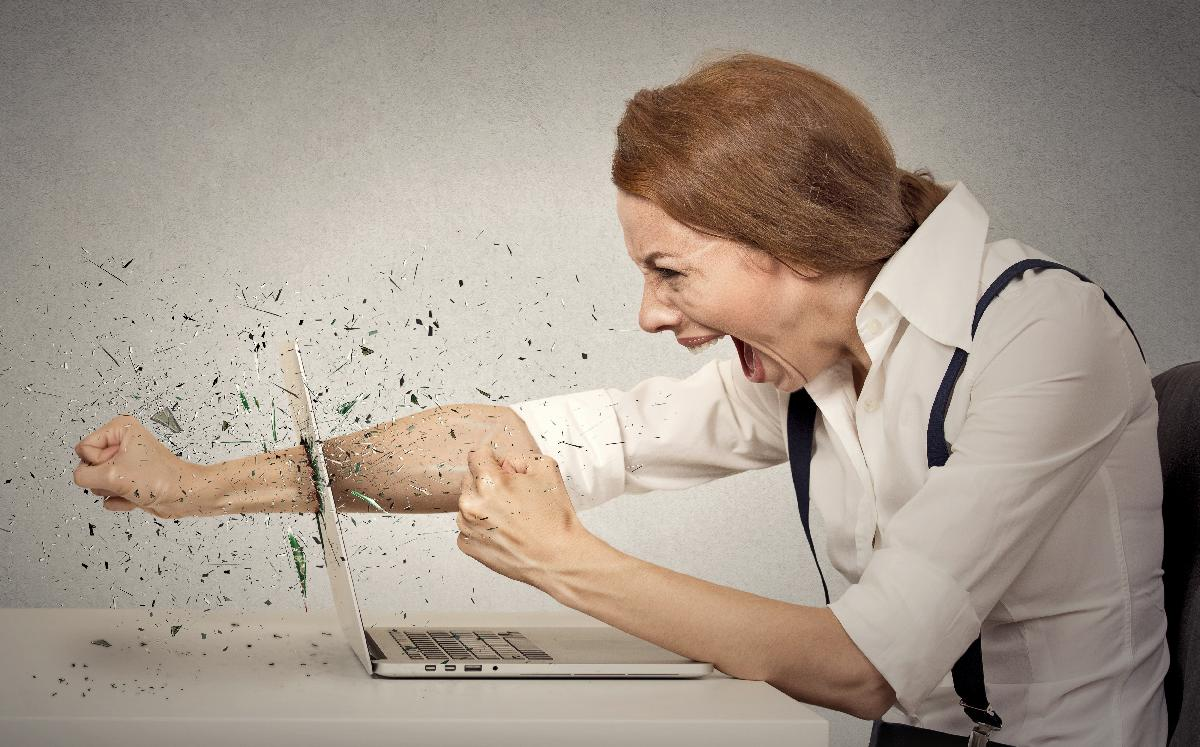

When to put input data by hand?

- If it takes less than a minute

- if your data isn't in electronic form 

## GUI

The variable area of the HOME tab allows you to

- create, edit, and save variables in your workspace

- import all or a portion of .txt, .xls, .csv, .mat, .dat files

- see and name columns of data in file

`uiimport` - command brings up the import GUI

## Command Line Commands

`load` – loads numeric variables into MATLAB

`csvread` – loads numeric values from a .csv file 

`xlsread` – loads texts and numeric values from .xls, .xlsx, .xlsm, .xltx, and .xltm files 

`readtable` – creates a table of variables from the columns of a file

`textscan`  - reads formatted text into a cell array 

`importdata` – loads data (including images) from a file, can specify delimiter and column headings 

## `LOAD`

- works for many file types, (but usually only ascii files,** really I would only use this for .mat files**)

- otherwise data should be numeric – is imported as doubles

load(matfile)

## `IMPORTDATA`

- most general of the functions (can import images)

- can specify delimiter (`delimiterIn`) and header lines (`headerlinesIn`)

- can output MATLAB's best guess at column delimiter (`delimiterOut`) and number of header lines (`headerlinesOut`)

Example setting `' '` (space) as a delimiter (what separates values). importdata reads .csv files well enough.

txtimport = importdata(txtfile," ") 

txtimport = 	1.0e+03 *

   1.850000000000000  -0.000373000000000  -0.000425000000000  -0.000339000000000  -0.000502000000000  -0.000243000000000  -0.000536000000000  -0.000210000000000  -0.000515000000000  -0.000238000000000  -0.000591000000000  -0.000162000000000
   1.851000000000000  -0.000218000000000  -0.000274000000000  -0.000184000000000  -0.000350000000000  -0.000086000000000  -0.000368000000000  -0.000068000000000  -0.000365000000000  -0.000081000000000  -0.000429000000000  -0.000016000000000
   1.852000000000000  -0.000228000000000  -0.000280000000000  -0.000196000000000  -0.000353000000000  -0.000103000000000  -0.000378000000000  -0.000078000000000  -0.000367000000000  -0.000098000000000  -0.000434000000000  -0.000030000000000
   1.853000000000000  -0.000269000000000  -0.000321000000000  -0.000239000000000  -0.000378000000000  -0.000160000000000  -0.000428000000000  -0.000110000000000  -0.000393000000000  -0.000155000000000  -0.000472000000000  -0.000075000000000
   1.8540000

csvimport = importdata(csvfile)

csvimport = 	1.0e+03 *

   1.700500000000000   0.008300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.701500000000000   0.018300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.702500000000000   0.026700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.703500000000000   0.038300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.704500000000000   0.060000000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.705500000000000   0.096700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.706500000000000   0.048300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.707500000000000   0.033300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.708500000000000   0.016700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.709500000000000   0.013300000000000  -0.001000000000000  -0.00

## `CSVREAD`

- works for .csv files containing strictly numeric values

- stores all values in large matrix M

- can start at arbitrary column and row, *R1 C1 …*

Example using .csv file 

csv = csvread(csvfile)

csv = 	1.0e+03 *

   1.700500000000000   0.008300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.701500000000000   0.018300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.702500000000000   0.026700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.703500000000000   0.038300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.704500000000000   0.060000000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.705500000000000   0.096700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.706500000000000   0.048300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.707500000000000   0.033300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.708500000000000   0.016700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.709500000000000   0.013300000000000  -0.001000000000000  -0.00100000

## `XLSREAD`

- reads all numeric data into the matrix X 

- can specify excel sheet and range

- can include output variables to capture text

Example using a quite complicated .xlsx file

Xlsx = xlsread(xlsfile, 'Global Carbon Budget','A23:F78')

Xlsx = 	1.0e+03 *

   1.961000000000000   0.002579723726845   0.001607579000000   0.001653600000000   0.000714842452714   0.000605098214760
   1.962000000000000   0.002685098813535   0.001566764000000   0.001187200000000   0.000756709067000   0.001348348648551
   1.963000000000000   0.002832715053775   0.001513809000000   0.001208400000000   0.000904996694143   0.000877794265315
   1.964000000000000   0.002993811446773   0.001463909000000   0.001038800000000   0.001141756645429   0.001400576014824
   1.965000000000000   0.003129407811660   0.001417684500000   0.002332000000000   0.001292828416571   0.000423229124380
   1.966000000000000   0.003287542540322   0.001376039000000   0.002332000000000   0.001276706707429   0.001278424412809
   1.967000000000000   0.003392742733550   0.001354775500000   0.001293200000000   0.001070205561429   0.001628393858540
   1.968000000000000   0.003565351976477   0.001353706500000   0.002098800000000   0.001100678372286   0.002530557659479
   1.96900000

[num,text,raw] = xlsread(xlsfile, 'Global Carbon Budget','A20:F79')

num = 	1.0e+03 *

   1.959000000000000   0.002453377862176   0.001810587500000   0.002035200000000   0.000852375910000   0.000516073203889
   1.960000000000000   0.002568376024197   0.001672592500000   0.001505200000000   0.000819016634429   0.001394030036021
   1.961000000000000   0.002579723726845   0.001607579000000   0.001653600000000   0.000714842452714   0.000605098214760
   1.962000000000000   0.002685098813535   0.001566764000000   0.001187200000000   0.000756709067000   0.001348348648551
   1.963000000000000   0.002832715053775   0.001513809000000   0.001208400000000   0.000904996694143   0.000877794265315
   1.964000000000000   0.002993811446773   0.001463909000000   0.001038800000000   0.001141756645429   0.001400576014824
   1.965000000000000   0.003129407811660   0.001417684500000   0.002332000000000   0.001292828416571   0.000423229124380
   1.966000000000000   0.003287542540322   0.001376039000000   0.002332000000000   0.001276706707429   0.001278424412809
   1.967000000

text = 1×6 cell array
    {'Year'}    {'fossil fuel and industry'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}


raw = 60×6 cell array
    {'Year'}    {'fossil fuel and industry'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'       }    {'land sink'        }
    {[1959]}    {[       2.453377862175623]}    {[        1.810587500000000]}    {[ 2.035200000000000]}    {[0.852375910000000]}    {[0.516073203889333]}
    {[1960]}    {[       2.568376024196962]}    {[        1.672592500000000]}    {[ 1.505200000000000]}    {[0.819016634428572]}    {[1.394030036021288]}
    {[1961]}    {[       2.579723726845251]}    {[        1.607579000000000]}    {[ 1.653600000000000]}    {[0.714842452714286]}    {[0.605098214759635]}
    {[1962]}    {[       2.685098813534764]}    {[        1.566764000000000]}    {[ 1.187200000000000]}    {[0.756709067000000]}    {[1.348348648551041]}
    {[1963]}    {[       2.832715053775487]}    {[        1.513809000000000]}    {[ 1.208400000000000]}    {[0.904996694142857]}    {[0.877794265314975]}
    {[1964]}    {[       2.993811446773101]}    {[    

The advanced option for reading data from an xlsx file may be to capture the headers as well. You can do this with the following

rawT = cell2table(raw(2:end,:))

rawT = 59×6 table
    Var1     Var2      Var3      Var4      Var5       Var6  
    ____    ______    ______    ______    _______    _______

    1959    2.4534    1.8106    2.0352    0.85238    0.51607
    1960    2.5684    1.6726    1.5052    0.81902      1.394
    1961    2.5797    1.6076    1.6536    0.71484     0.6051
    1962    2.6851    1.5668    1.1872    0.75671     1.3483
    1963    2.8327    1.5138    1.2084      0.905    0.87779
    1964    2.9938    1.4639    1.0388     1.1418     1.4006
    1965    3.1294    1.4177     2.332     1.2928    0.42323
    1966    3.2875     1.376     2.332     1.2767     1.2784
    1967    3.3927    1.3548    1.2932     1.0702     1.6284
    1968    3.5654    1.3537    2.0988     1.1007     2.5306
    1969     3.779    1.3627    2.7984     1.

match = [" " , "-"];
newraw = erase(raw(1,:),match);
% spaces are no good in table header names
rawT.Properties.VariableNames = newraw

rawT = 59×6 table
    Year    fossilfuelandindustry    landusechangeemissions    atmosphericgrowth    oceansink    landsink
    ____    _____________________    ______________________    _________________    _________    ________

    1959           2.4534                    1.8106                 2.0352           0.85238     0.51607 
    1960           2.5684                    1.6726                 1.5052           0.81902       1.394 
    1961           2.5797                    1.6076                 1.6536           0.71484      0.6051 
    1962           2.6851                    1.5668                 1.1872           0.75671      1.3483 
    1963           2.8327                    1.5138                 1.2084             0.905     0.87779 
    1964           2.9938          

## `READTABLE`

- creates a table from column data in a file

- `T` contains one variable per column in data file

Ttxt = readtable(txtfile)

Ttxt = 171×12 table
    Var1     Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10     Var11     Var12 
    ____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    1850    -0.373    -0.425    -0.339    -0.502    -0.243    -0.536     -0.21    -0.515    -0.238    -0.591    -0.162
    1851    -0.218    -0.274    -0.184     -0.35    -0.086    -0.368    -0.068    -0.365    -0.081    -0.429    -0.016
    1852    -0.228     -0.28    -0.196    -0.353    -0.103    -0.378    -0.078    -0.367    -0.

Tcsv = readtable(csvfile)

Tcsv = 316×5 table
     Var1     Var2    Var3    Var4    Var5
    ______    ____    ____    ____    ____

    1700.5     8.3     -1      -1      1  
    1701.5    18.3     -1      -1      1  
    1702.5    26.7     -1      -1      1  
    1703.5    38.3     -1      -1      1  
    1704.5      60     -1      -1      1  
    1705.5    96.7     -1      -1      1  
    1706.5    48.3     -1      -1      1  
    1707.5    33.3     -1      -1      1  
    1708.5    16.7     -1      -1      1  
    1709.5    13.3     -1      -1      1  
    1710.5       5     -1      -1      1  
    1711.5       0     -1      -1      1  
    1712.5       0     -1      -1      1  
    1713.5     3.3     -1      -1      1  
    1714.5    18.3     -1      -1      1  
    1715.5      45     -1      -1      1  


Txls = readtable(xlsfile) % No so good with excel files

Txls = 31×1 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       TheGlobalCarbonBudget2018IsACollaborativeEffortOfTheGlobalCarbo                                                                                                                                                                                                               

## `TEXTSCAN`

- reads formatted data from a file or string (must use `fopen``() `and `fclose``()`)

- stores any type of data in cell array *C*

- must specify the exact format in <`formatSpec`> using *conversion specifiers*

- this function is also good at filtering through character and string arrays based on conversion specifiers

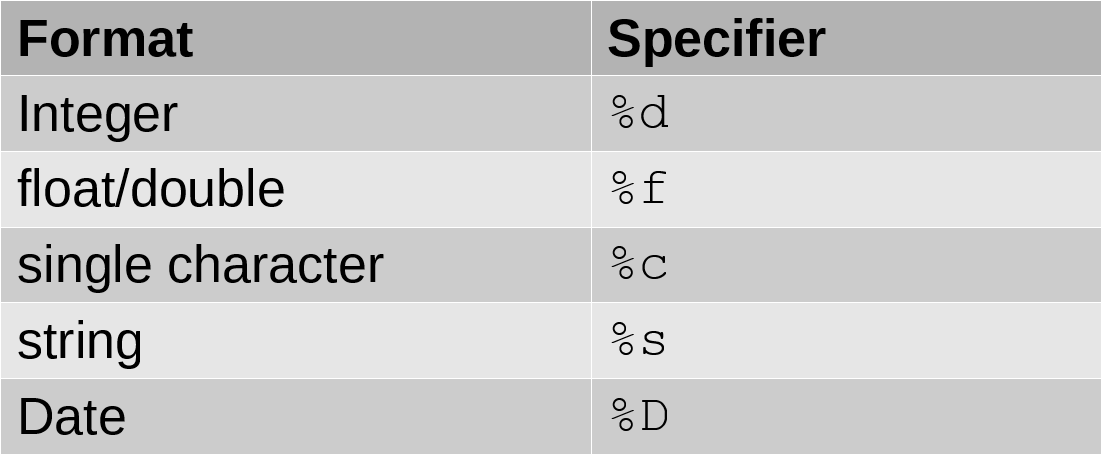

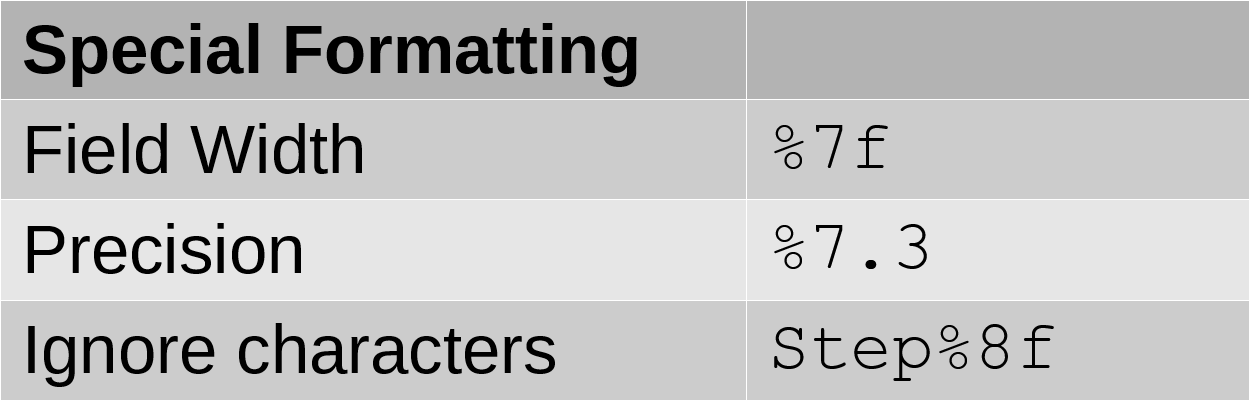

fid = fopen(txtfile)

fid = 4

N = 171;
scantxt = textscan(fid,'%f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f',N)

scantxt = 1×12 cell array
    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}    {171×1 double}


fclose(fid);

## Outputting Data

Saving your processed variables is a good idea

Save your workspace (.mat files)

Output the data into a file with commands

- `dlmwrite`

- `csvwrite`

- `xlswrite`

- `writetable`

## `DLMWRITE`

- writes the data array *M* to `<filename> `(any ascii file)

- adds to an existing file with `'-append'`

- specify delimiter or row/column offsets with `Name,Value`pairs or further arguments

## `CSVWRITE`

- writes data array *M *to a *.csv*file

- specify starting row and column of the *.csv*file with <row> and <col>

- *M *must be numeric

- *.csv *file carries only 5 digits of precision   

## `XLSWRITE`

- writes data array *A *to an excel spreadsheet

- *A *can be any type of array

- specify specific sheets and cell ranges to write data to the spreadsheet

## `WRITETABLE`

- writes table *T* to <filename> OR *T.txt*

- each column of each variable in *T *becomes a column in the output file

- variable names of *T* become column headings in the first line of the file